% Os dois primeiros exemplos são testes de conceito.

## Conexões não implementadas

Ainda não temos nenhuma conexão diferente de TCP.

Reserva para em caso no futuro seja desejável outras formas de conexão.

E para ajudar a desacoplar e permitir sobrecarga de métodos.

% try     
%     Analysers.Analyser.connGPIB('1234')
% catch exception
%     disp(exception.message)
% end

## Execução com o simulador SA2500PC

Alocação dinâmica ainda não implementada (perfumaria prevista):

Caso só passe o IP, teríamos uma opção de auto discovery:

% % Auto discovery
% try     
%     Analysers.Analyser.connTCP("localhost");
% catch exception
%     disp(exception.message)
% end
% 
% % Ref. portas a varrer:
% % 5025  - Keysight e R&S
% % 5555  - R&S EB500
% % 9001  - Anritsu
% % 34835 - Tektronix 

Instrumento simulado (Download em [SA2500PC](https://anatel365-my.sharepoint.com/:f:/r/personal/eric_anatel_gov_br/Documents/Softwares/Tektronix/SA2500PC?csf=1&web=1&e=Qde3u5)).

Conectado e respondendo à sua identificação:

% disp('Propriedades:')
% callTCP = Analysers.Analyser.connTCP("localhost", 34835) % Simulador
callTCP = Analysers.Analyser.connTCP("192.168.48.2", 34835)

callTCP =   dictionary (string ⟼ string) with 6 entries:

    "Factory" ⟼ "TEKTRONIX"
    "model"   ⟼ "SA2500"
    "serial"  ⟼ "B040211"
    "version" ⟼ "7.050"
    "ip"      ⟼ "192.168.48.2"
    "port"    ⟼ "34835"


## **Instância dinâmica. **

Cada fabricante deve ter, na pasta 'Analysers', sua classe como mesmo nome de sua superclasse (prop:Factory), e cada especifidade de um certo modelo (prop:model) deve estar com o mesmo nome, o que permite escalonar e isolar os componentes em uma interface unificada, e granularizada para o serviço esperado.

O 'Analyser' deve conter todos os comandos genéricos da SCPI (Standard Commands for Programmable Instruments) e IEEE 488.2 Common Commands, este último inicia por um asterisco..

Com base na IDN que o instrumento responde, a instância sempre herda todos os comandos do 'Analyser'.

No caso, o "is a" está representado no classdef como "classdef TEKTRONIX < Analyser", ou seja, Um Tektronix é um analisador, e o SP2500 é um Tektronx ("classdef SA2500PC < TEKTRONIX")

Neste caso herda os comuns e sobrecarrega os comandos do Tektronix, e os específicos do modelo SA2500PC:

disp('Instancia Classes:')

Instancia Classes:


obj = Analysers.Analyser.instance(callTCP);

    "Analyer: Base de comando do fabricante"    "TEKTRONIX"



O simulador fecha quando recebe o comando de reset, então só fingimos o reset para evitar isso (na implementação específica do modelo). O que ainda oportuna outros casos de uso em casos diferentes, como o EB500 que precisa abrir uma porta específica para receber stream UDP.

Um instrumento real não terá o sufixo PC e portanto automaticamente não herdará esse método, o que possibilita compartilar comandos e especificar no modelo o que for diferente nele.

Aplicando uma sobrecarga no modelo SA2500PC com a resposta da classe:

obj.scpiReset;

Analyer.scpiReset: Criando nova conexão TCP.


Comandos gerais de inicialização:

obj.startUp()

TEKTRONIX: Start Ok.


Teste geral de conectividade (SCPI):

obj.ping()

Analyser.ping: Mesma conexão
Analyser.ping: Resposta IDN recebida:
TEKTRONIX,SA2500,B040211,7.050


Obtém parâmetros do objeto: 

disp('getSpan:')

getSpan:


disp(obj.getSpan())

200000000



disp('Parâmetros:')

Parâmetros:


obj.getParms()

ans =   dictionary (string ⟼ string) with 10 entries:

    "Function"  ⟼ "NORM"
    "AVGCount"  ⟼ "20"
    "Detection" ⟼ "POS"
    "UnitPower" ⟼ "DBM"
    "FStart"    ⟼ "759000000"
    "FStop"     ⟼ "959000000"
    "ResAuto"   ⟼ "1"
    "Res"       ⟼ "200000"
    "InputGain" ⟼ "0"
    "Att"       ⟼ "50"


## Operação

Aqui perguntamos se o parâmetro corresponde ao que foi solicitado (assert). E verificamos as respostas no simulador em tempo real:

disp('Pausas para observar o comportamento:')

Pausas para observar o comportamento:



% Esse bloco try é para liberar a conexão em caso de erro.
try

    %pause(5) % tempo para ajuste manual de teste.

    
    % % Testes
    % obj.setFreq(120000000)
    % obj.setSpan(50000)
    % assert(str2double(obj.getSpan) == 50000, 'O Span não foi ajustado.')
    % obj.setRes(2000)
    % assert(str2double(obj.getRes) == 2000, 'O Span não foi ajustado.')
    % 
    pause(1)
    obj.setFreq(100000000)
    obj.setSpan(10000)
    
    % disp('Nova conexão simulada pelo ping (caso não responda):')
    % obj.conn = [];
    
    % Isso gera um alerta na janela do simulador,
    % mas não retorna erro.
    % try
    %     RBW = obj.getRes();
    %     assert(str2double(RBW) == 2000, 'A Resolução foi alterada automaticamente.')
    % catch exception
    %     disp('Resolução alterada automaticamente para:')
    %     disp(RBW)
    % end
    
    pause(1)
    disp('Amostra em faixa larga')

Amostra em faixa larga


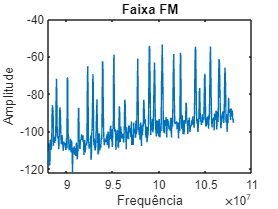

    obj.setFreq(88000000, 108000000)
    obj.setRes(20000) % Warning: Data out of range

    wtrace = obj.getTrace(1);

    plot(wtrace.freq,wtrace.value,"DisplayName","value");

    % Add xlabel, ylabel, title, and legend
    xlabel("Frequência");
    ylabel("Amplitude");
    title("Faixa FM");

    legend('off');
    % drawnow;
    
    % try
    %     assert(str2double(obj.getSpan) == 10000, 'O Span não foi ajustado.')
    % catch
    %     disp('Se atribuir o span depois gera erro "out of range"')
    % end
    
    % pause(1)
    % % Observar que o com Spectrum o RBW Auto em verde
    % obj.setRes('Auto')
    % obj.setFreq(88000000, 108000000)
    
    % Para observar a faixa em auto level
    pause(2)

    % Escolhe uma portadora FM para análise
    freq = 100300000;
    
    obj.setSpan(500000)
    obj.setFreq(freq)
    assert(str2double(obj.getSpan) == 500000, 'O Span não foi ajustado.')
    
    %obj.preAmp('On')
    
    % % Teste dos níveis de atenuação (comentado para poupar tempo)
    % % Para observar abrir o menu Spectrum -> More -> Ampl
    % for attstep = 5:5:50
    %     obj.setAtt(attstep);
    %     pause(0.5)
    % 
    %     % O pré desativa sozinho com att acima de 15dB
    %     % Mesmo expressamente solicitado, sem erro:
    %     obj.preAmp('On')
    % end




    trace = obj.getTrace(1);

    disp('Trace:')

Trace:


    
    % Só as 5 primeiras linhas
    disp(trace (1:5,:));

       freq        value 
    __________    _______

    1.0005e+08    -123.24
    1.0005e+08     -112.9
    1.0005e+08    -112.84
    1.0005e+08    -116.94
    1.0005e+08    -119.11



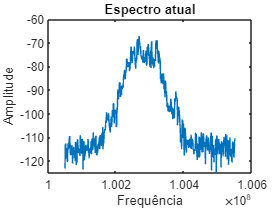

    
    
    
    % Plota o Trace
    plot(trace.freq,trace.value,"DisplayName","value");
    
    % Add xlabel, ylabel, title, and legend
    xlabel("Frequência");
    ylabel("Amplitude");
    title("Espectro atual");

    legend('off');


    trcs = fcn.getTracesFromUnit(obj, 30);

ans = "Trace 1"

ans = "Trace 2"

ans = "Trace 3"

ans = "Trace 4"

ans = "Trace 5"

ans = "Trace 6"

ans = "Trace 7"

ans = "Trace 8"

ans = "Trace 9"

ans = "Trace 10"

ans = "Trace 11"

ans = "Trace 12"

ans = "Trace 13"

ans = "Trace 14"

ans = "Trace 15"

ans = "Trace 16"

ans = "Trace 17"

ans = "Trace 18"

Analyser: Aguardando sincronismo (1/2): ...
:INITiate:IMMediate;


ans = "Trace 19"

ans = "Trace 20"

ans = "Trace 21"

ans = "Trace 22"

ans = "Trace 23"

ans = "Trace 24"

ans = "Trace 25"

ans = "Trace 26"

ans = "Trace 27"

ans = "Trace 28"

ans = "Trace 29"

ans = "Trace 30"


    % Verificação adicional.
    if isnan(trcs)
        warning('Trace com NaN')
    end

    disp("Total size:")

Total size:


    size(trcs)

ans =     30   501


    disp(trcs)

 -119.4926 -114.6828 -113.1192 -114.9349 -115.4292 -115.4454 -113.9077 -112.6733 -119.2177 -109.0816 -112.4341 -109.2080 -110.1505 -113.8634 -118.7390 -114.7565 -117.0147 -121.5669 -115.2975 -118.4797 -115.3132 -113.0894 -110.4898 -114.3923 -112.0792 -108.9402 -114.2784 -113.9662 -115.4977 -120.0839 -118.4200 -116.7708 -112.6708 -114.1209 -112.1777 -114.7666 -110.5296 -112.8642 -112.3876 -114.4344 -115.9307 -113.8612 -116.2174 -119.6661 -117.5965 -109.6255 -106.7665 -112.0616 -111.6475 -113.6195 -115.0594 -119.1938 -111.8329 -113.8164 -114.7432 -111.5070 -112.0315 -117.6892 -115.4833 -109.9285 -109.8755 -110.9384 -111.1428 -109.3394 -116.3397 -112.9786 -114.0982 -115.4902 -113.3802 -115.1406 -111.8097 -120.6978 -112.3231 -110.2912 -115.0899 -119.1678 -120.0835 -115.9774 -116.1167 -115.3599 -116.5210 -118.4330 -114.9941 -109.5805 -112.0787 -114.1460 -115.5334 -115.3157 -113.4521 -114.1250 -111.8863 -110.4666 -111.2099 -116.2508 -116.4545 -111.4077 -115.8415 -114.8410 -118.6854 -117.4459


    % Um tempo para o analisador respirar
    % Porque eventualmente ele não responde
    pause(0.2)

    freq = 100300200;
    obj.setFreq(freq)
    disp('Leitura do marcador:')

Leitura do marcador:


    nivel = obj.getMarker(freq, 1);
    fprintf('Em %i MHz o nível é: %f\n', freq, nivel);

Em 100300200 MHz o nível é: -72.348274



    if isnan(nivel)
        warning('Nível não retornado.');
    end

catch exception
    % Encerra ativamente a conexão
    % Para liberar a porta em caso de erro
    obj.disconnect();
    error('TestTektronix: %s', exception.identifier);
end

% Se tudo der certo, encerra a conexão.
obj.disconnect()


disp("Pronto")

Pronto
